## Get Data

filename = '/home/martian/Project-ABG/ABG_classification/data/pngs';
[testIMDS,validationIMDS,trainingIMDS] = get_rand_abgo_imds(filename);


## Resize the data

%resize datastore to [224, 224, 3]
train_audIMDS = augmentedImageDatastore([224, 224, 3], trainingIMDS);
validation_audIMDS = augmentedImageDatastore([224, 224, 3], validationIMDS);
test_audIMDS = augmentedImageDatastore([224, 224, 3], testIMDS);

% Important datastores have been resized to fit specified for
% the model
train_audIMDS;
validation_audIMDS;
test_audIMDS;
% end of data split


mobnet_trained = load('TrainedMob2.mat');
net = mobnet_trained.net;
% analyzeNetwork(net)    % uncomment to analyze network


% layer + features
layer = 'block_11_add';
featuresTrain = activations(net,train_audIMDS,layer);
featuresTest = activations(net,test_audIMDS,layer);
whos featuresTrain

  Name                Size                        Bytes  Class     Attributes

  featuresTrain      14x14x96x7891            593908224  single              




featuresTrain = squeeze(mean(featuresTrain,[1 2]))';
featuresTest = squeeze(mean(featuresTest,[1 2]))';
whos featuresTrain

  Name                  Size              Bytes  Class     Attributes

  featuresTrain      7891x96            3030144  single              



### SVM templates 

% t_1 = templateSVM( ...
%      'Standardize','on', ...
%      'KernelFunction','gaussian' ...
%      );

t1 = templateSVM('BoxConstraint',0.7, ...
   'KernelFunction','rbf', ...
   'DeltaGradientTolerance',1e-2, ...
   'Solver','SMO', ...
   'Standardize',false);

t2 = templateSVM('BoxConstraint',0.475, ...
 'KernelFunction','polynomial', ...
 'DeltaGradientTolerance',1e-3, ...
 'PolynomialOrder',1, ...
 'Solver','ISDA', ...
 'Standardize',true);

t3 = templateSVM('BoxConstraint',0.015, ...
   'KernelFunction','linear', ...
   'DeltaGradientTolerance',1e-2, ...
   'Solver','ISDA', ...
   'Standardize',true);

t4 = templateSVM('BoxConstraint',1, ...
   'KernelFunction','gaussian', ...
   'DeltaGradientTolerance',1e-2, ...
   'Solver','SMO', ...
   'Standardize',false...
   );

template = {t1,t2,t3,t4};

### Classify, Predict, Confusion Matrices and F-Scores

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


accuracy = 0.8700

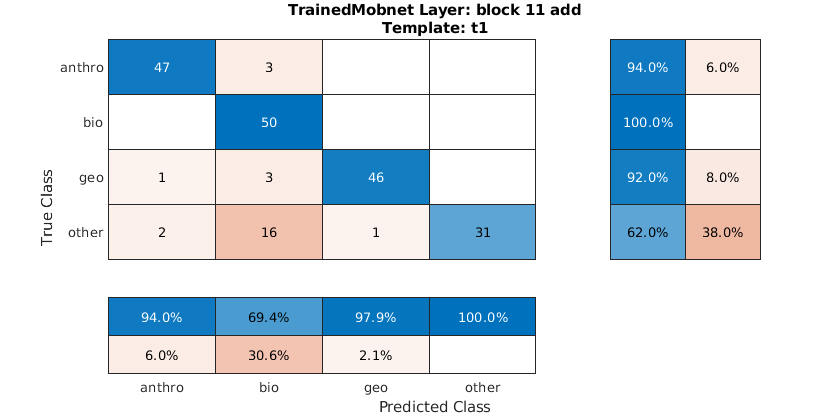

accuracy = 0.8700

fScore =     0.9400    0.8197    0.9485    0.7654


avg_f_score = 0.8684

accuracy = 0.8150

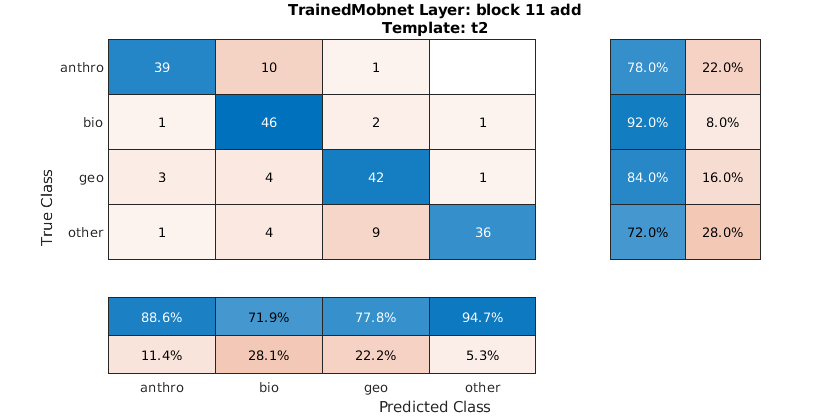

accuracy = 0.8150

fScore =     0.8298    0.8070    0.8077    0.8182


avg_f_score = 0.8157

accuracy = 0.8150

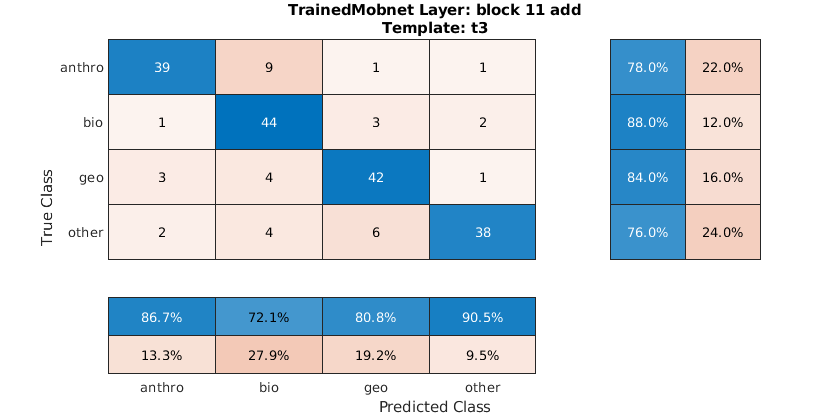

accuracy = 0.8150

fScore =     0.8211    0.7928    0.8235    0.8261


avg_f_score = 0.8159

accuracy = 0.9650

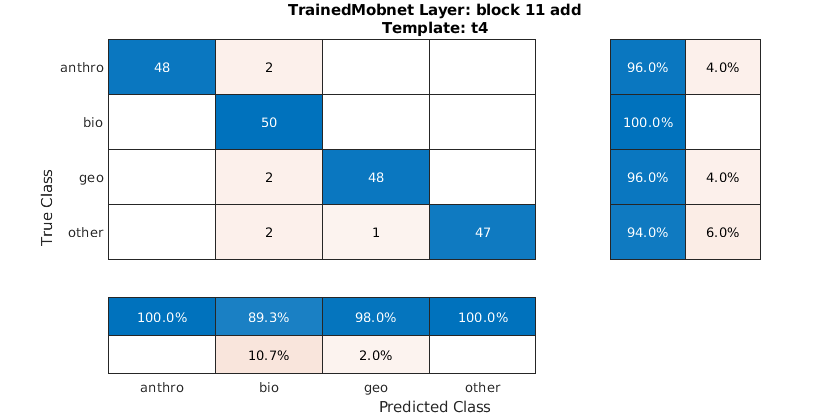

accuracy = 0.9650

fScore =     0.9796    0.9434    0.9697    0.9691


avg_f_score = 0.9654

accuracy = 0.9650

scores = 200×4 single matrix
         0   -0.2636   -0.2861   -0.4609
         0   -0.2465   -0.3298   -0.4429
   -0.0145   -0.2221   -0.3235   -0.4399
   -0.0283   -0.1978   -0.3301   -0.4438
   -0.0583   -0.2193   -0.2658   -0.4566
   -0.0412   -0.1332   -0.3645   -0.4612
   -0.0000   -0.2748   -0.3587   -0.3666
   -0.0129   -0.2249   -0.3237   -0.4385
   -0.0433   -0.1467   -0.3328   -0.4772
         0   -0.2731   -0.2796   -0.4700


for i=1:size(template,2)
    classifier = fitcecoc( ...
        featuresTrain, ...
        trainingIMDS.Labels, ...
        'Learners',template(i), ...
        'Options',statset('UseParallel',true) ...
        );
    
    
    YPred = predict(classifier,featuresTest);
    accuracy = mean(YPred == testIMDS.Labels)
    
    % Displaying confusion chart
    fig = figure;
    fig_Position = fig.Position;
    fig_Position(3) = fig_Position(3)*1.5;
    fig.Position = fig_Position;
    cm = confusionchart(testIMDS.Labels,YPred,'RowSummary','row-normalized','ColumnSummary','column-normalized');
    title(cm,{"TrainedMobnet Layer: block 11 add","Template: t"+i})
    
    % Calculating fScore and avg_f_score
    cm1 = cm.NormalizedValues;
    
    for i = 1:size(cm1,1)
        precision(i) = cm1(i,i)/sum(cm1(i,:));
    end
    
    for i = 1:size(cm1,1)
        recall(i) = cm1(i,i)/sum(cm1(:,i));
    end
    
    for i = 1:size(precision,2)
        fScore(i) = (2 * (precision(i) * recall(i)) / (precision(i) + recall(i)));
    end
    
    % Displaying results
    accuracy
    fScore
    avg_f_score = sum(fScore)/numel(fScore)
end